# SDR

Generate IOT signals

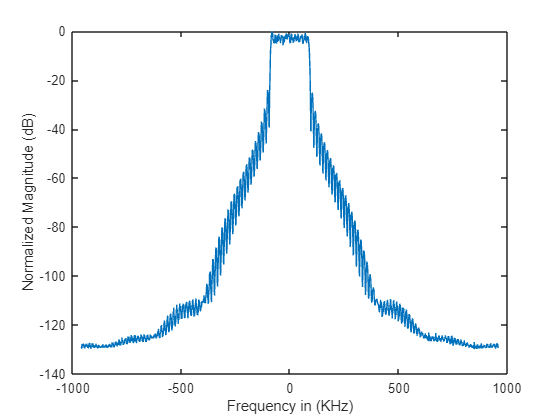

n_devices = 6;

[waveform,Fs] = Generate_NBiot();
[signal,f] = pwelch(waveform,2048,1024,2048,Fs);
signal = fftshift(signal/max(abs(signal)));
figure;
F= f - f(length(f)/2+1);
plot(F/1e3,20*log10(signal))
xlabel('Frequency in (KHz)')
ylabel('Normalized Magnitude (dB)')

B = 200e3*7;
Fs_up = 2*B;
up_factor = ceil(Fs_up/Fs);
upsampled_sig = upsample(signal,up_factor);


filtered_upsampled_sig = filter(TX_filter,upsampled_sig);
F_new = linspace(2*F(2),2*F(end)+1,length(filtered_upsampled_sig));
F_new = 2*F(1): 937.5:2*F(end)+937.5;
hold on;
plot(F_new/1e3,(20*log10(filtered_upsampled_sig)))

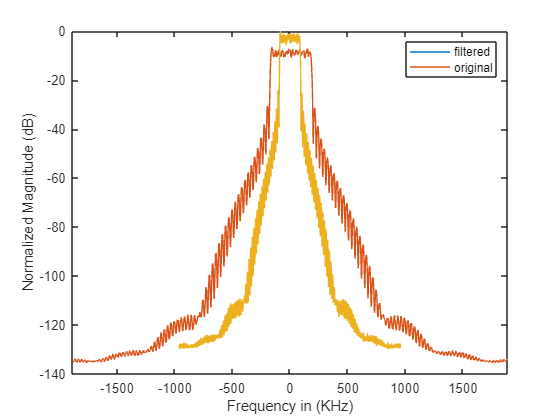

plot(F/1e3,20*log10(signal))
xlabel('Frequency in (KHz)')
ylabel('Normalized Magnitude (dB)')
xlim([-1885 1885])
legend('filtered','original')
hold off;

filtered_upsampled_sig = filter(TX_filter_complex_flat_top,upsampled_sig);
F_new = linspace(2*F(2),2*F(end)+1,length(filtered_upsampled_sig));
F_new = 2*F(1): 937.5:2*F(end)+937.5;
figure;
hold on;
plot(F_new/1e3,(20*log10(filtered_upsampled_sig)))

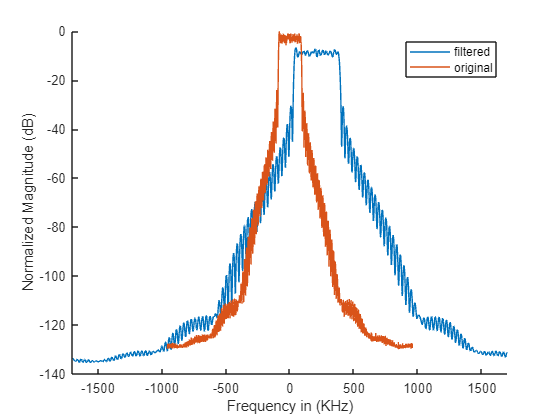

plot(F/1e3,20*log10(signal))
xlabel('Frequency in (KHz)')
ylabel('Normalized Magnitude (dB)')
xlim([-1700 1700])
legend('filtered','original')
hold off;

### NB-IOT Applications

- Health Monitoring Systems:

- Real-time Patient Monitoring: NB-IoT-enabled wearables and health devices provide real-time monitoring of patients' vital signs. For example, continuous monitoring of heart rate, blood pressure, and glucose levels can be transmitted to healthcare providers, enabling early intervention and personalized healthcare.

- Epidemic Surveillance: In the context of public health, NB-IoT can be crucial for tracking and managing epidemics. Sensors in populated areas can monitor the spread of diseases, helping authorities implement targeted measures and allocate resources more efficiently.

- Remote Patient Management: Patients with chronic conditions can benefit from remote monitoring through NB-IoT devices. This not only enhances patient comfort but also reduces the burden on healthcare facilities, allowing them to focus on critical cases.

        2. Smart Surveillance:

- Anomaly Detection: Smart surveillance systems using NB-IoT-connected cameras and sensors can detect unusual patterns or behaviors in public spaces. This technology can automatically alert law enforcement or emergency services in the event of suspicious activities, improving overall **public safety.**

- Traffic Flow Optimization: NB-IoT plays a crucial role in smart traffic management, optimizing traffic lights based on real-time data. This not only reduces traffic congestion but also enhances **road safety** by preventing accidents and promoting smoother traffic flow.

- Emergency Response: In the case of accidents or emergencies, smart surveillance systems can provide instant information to emergency services, enabling a quicker and more effective response. This is particularly valuable in densely populated urban areas.

        3. Waste Management:

- Optimized Collection Routes: NB-IoT-connected waste bins equipped with sensors can communicate their fill levels in real-time. Waste management companies can use this data to optimize collection routes, reducing unnecessary trips and minimizing fuel consumption and emissions.

- Environmental Impact Assessment: By monitoring waste composition and generation patterns through IoT devices, municipalities can assess the environmental impact of different waste streams. This information can guide policies aimed at promoting recycling and reducing overall waste production.

- Smart Recycling Initiatives: NB-IoT can be employed to create smart recycling systems. For example, smart bins can provide incentives for recycling through rewards or discounts, encouraging citizens to actively participate in sustainable waste management practices.

### References:

- Steinhubl, S. R., Muse, E. D., & Topol, E. J. (2015). Can mobile health technologies transform health care? JAMA, 314(12), 1235-1236.

- Kaur, H., & Sandhu, K. (2018). Smart surveillance: A review. Journal of Ambient Intelligence and Humanized Computing, 9(2), 491-516.

- Perera, C., Zaslavsky, A., Christen, P., & Georgakopoulos, D. (2014). Context aware computing for the Internet of Things: A survey. IEEE Communications Surveys & Tutorials, 16(1), 414-454.